*Hande Yildirim, 141201047, Ele515, Final Proje*

# **PROJENIN AMACI**

Son yıllarda dünyada olduğu gibi Türkiye’de de geri dönüşüme verilen değer artmıştır. Özellikle büyük üretim alanına sahip fabrikalarda eksik veya yanlış üretilmiş olan bazı parça ve maddeler geri dönüştürülme ünitelerine gönderilmektedir. Örneğin daha önce stajımı yapmış olduğum Arçelik Buzdolabı İşletmesi buna iyi bir örnektir. Kullanılmayacak veya satışa sunulamayacak buzdolapları geri dönüştürülmektedirler. Geri dönüştürülerek elde edilen malzemeler özellikle çimento fabrikalarına gönderilmektedirler. Bunun için geri dönüşüm ünitesi sonrasında belli bir havuz bulunmaktadır ve burada çimento fabrikasına gönderilmesi gereken ürünler belli kutular içerisinde buraya gelerek biriktirilirler. Bu işlem sırasında kutuların her birinin belli mesafelerde bulunarak otomatik olarak taşınmaları gerekmektedir. Bazen kutular denge sağlayamayıp ileri veya geri fazla giderek birbirlerine çarparlar ve bu durum kırılmalara neden olmaktadır. Bunun sonucunda elde edilen geri dönüşüm malzemeleri de ne yazık ki dağılmaktadırlar. Bu durum aslında küçük bir olaymış gibi görünse de maliyet açısından çimento fabrikalarını ciddi ölçülerde etkilemektedir. Çünkü bu fabrikalar ham madde alımı için yüksek maliyet ödemektedirler. Buzdolabı fabrikasından çıkarılan tek 1 kasa bile çimento fabrikası için maliyet açısından oldukça kıymetlidir. İşte bu nedenle bu projede bu mali kayıpları minimuma indirebilmek amacıyla geri dönüşüm atığı yani bir nevi başka fabrikalar için hammadde taşıyan her iki kutu arasına belli bir yay sabitine sahip değerde bir yay sistemi monte edilerek düzenli periyotlarda kullanılabilecek bir mekanizma tasarlanmıştır. Bu mekanizmanın kullanilacagi bant aşağıdaki şekildedir:

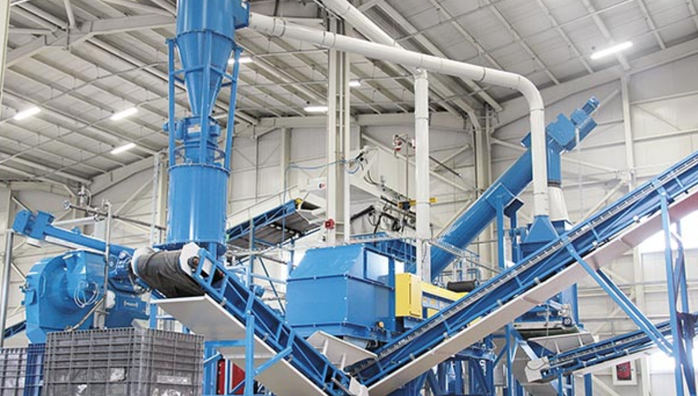

# **BOLUM1**

Tasarlanacak devre gorseli asagidaki gibidir:

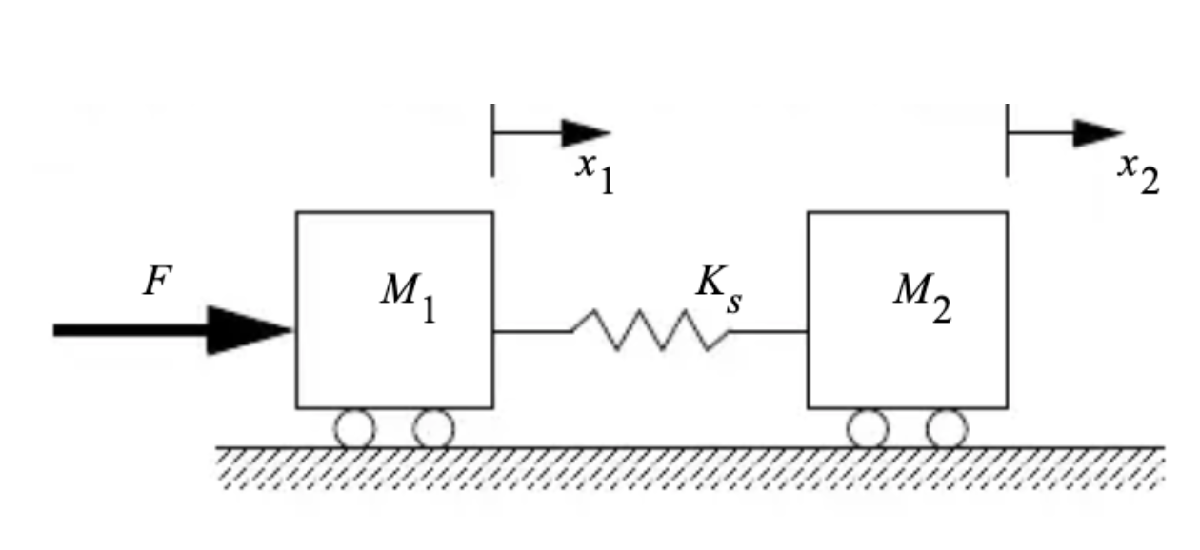

Oncelikle tasarlanacak sistem matrisleri ve constant degerler yazildi

M1 = 20; %M1 agirlik
M2 = 40; %M2 agirlik
Ks = 4; %yay sabiti

Buna uygun olarak kullanılacak denklemler aşağıdaki gibidir:


$$\sum{F_X=F+K_S\left(x_2-x_1\right)=M_1D^2x_1}$$



$$\sum{F_X=-K_S\left(x_2-x_1\right)=M_2D^2x_2} $$


Bu denklemler çözdürüldüğünde aşağıdaki matris elde edilir:


$$\frac{d}{\mathrm{dt}}\left\lbrack \begin{array}{c}
\mathrm{x1}\\
\mathrm{v1}\\
\mathrm{a1}\\
\mathrm{d1}
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & -\frac{\mathrm{Ks}\left(\mathrm{M1}+\mathrm{M2}\right)}{\mathrm{M1}*\mathrm{M2}} & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\mathrm{x1}\\
\mathrm{v1}\\
\mathrm{a1}\\
\mathrm{d1}
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
\frac{1}{\mathrm{M1}} & \frac{\mathrm{Ks}}{\mathrm{M1}*\mathrm{M2}}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_F \\
F
\end{array}\right\rbrack$$


Burada :

$a_F =\frac{1}{T^2 }$'dir.

Sistem matrisleri tanimlanir:

A = [ 0 1 0 0 ; 0 0 1 0 ; 0 0 0 1 ; 0 0 (-Ks * (M1+M2)/M1 * M2) 0];
B = [0 0 ; 0 0 ; 0 0 ; 1/M1 Ks/(M1*M2)];
C = [1 0 0 0];
D = [0];

State space sistemi olusturulur:

sistem = ss(A,B,C,D)


sistem =
 
  A = 
         x1    x2    x3    x4
   x1     0     1     0     0
   x2     0     0     1     0
   x3     0     0     0     1
   x4     0     0  -480     0
 
  B = 
          u1     u2
   x1      0      0
   x2      0      0
   x3      0      0
   x4   0.05  0.005
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



**Matlabda Sistem Simulasyonu**

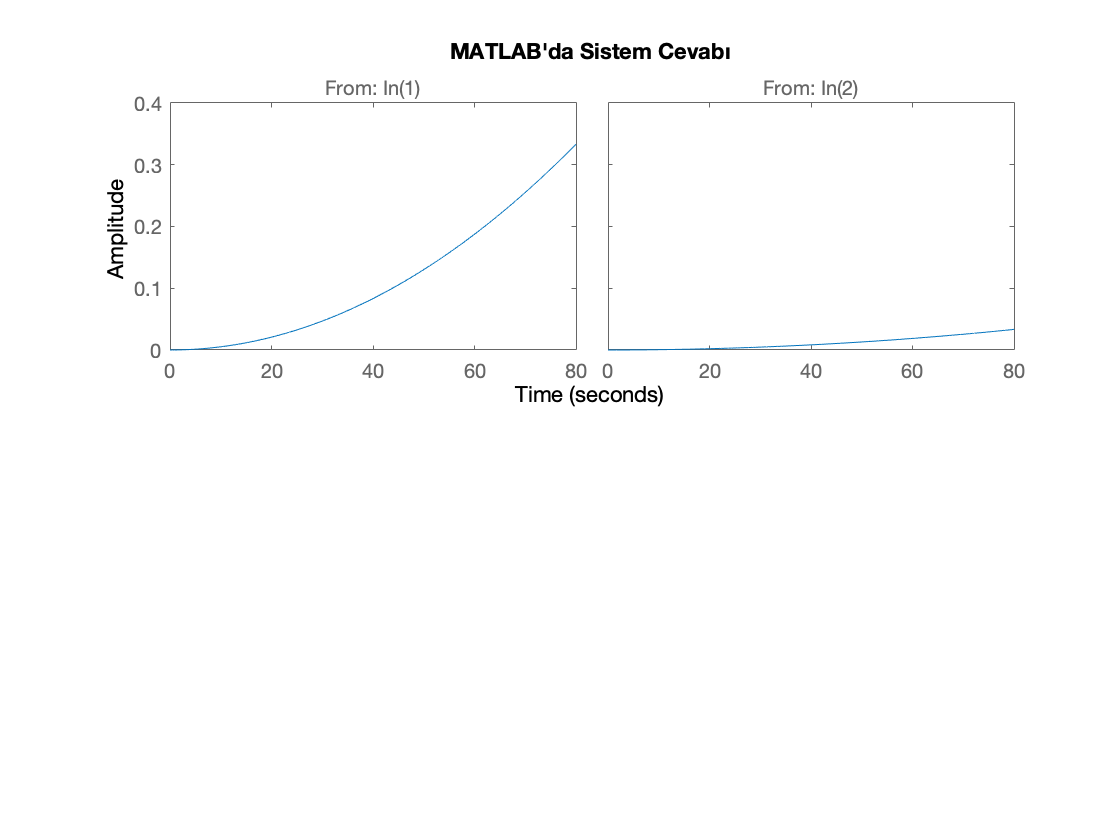

figure(1)
subplot(2,1,1)
step(sistem) %girdi olarak verilen birim basamaga gore sistem ciktisinin cizilmesi
title('MATLAB''da Sistem Cevabı')

**Simulinkte Sistem Simulasyonu**

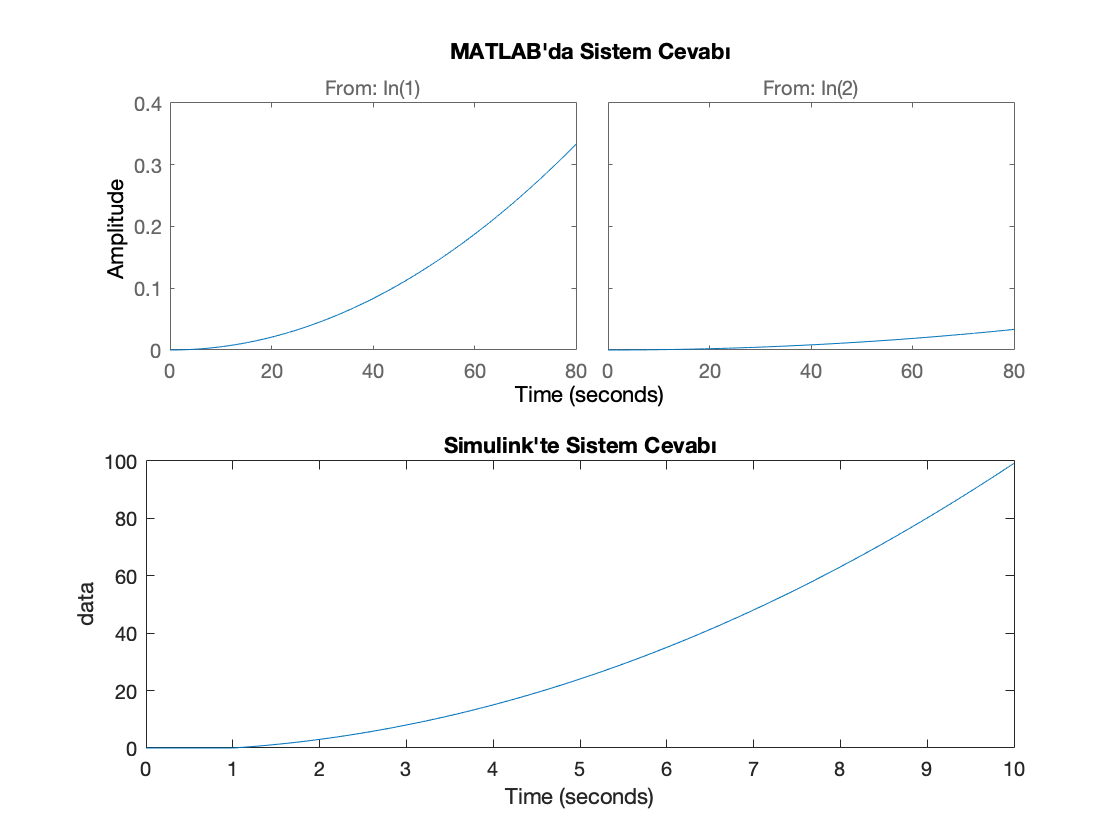

subplot(2,1,2)
model = sim('projesim1.slx'); %simulinkten dosyayı cagir
t = model.tout; %simulink zamanini belirle
sistem_out = model.sistem_out;
plot(sistem_out) %simulinke gore sistem ciktisi
title('Simulink''te Sistem Cevabı')

# **BOLUM 2**

**System Linearized Output With Kalman Filter System Output From Simulink**

model = sim('KALMAN1.slx');%model simulinkten cekilir
t = model.tout;%zaman cekilir

% d1 icin Kalman Filtresi uygulanmış toWorkspaceler Scripte cekilir
kal1 = model.kal1;
kal2 = model.kal2;
kal3 = model.kal3;

sist_out1 = model.out1;
sist_out2 = model.out2;
sist_out3 = model.out3;

sistem_out = model.sistem_out;

Yeni pencerede grafik cizimi icin figure olusturulur ve sonrasinda sistem cizilir

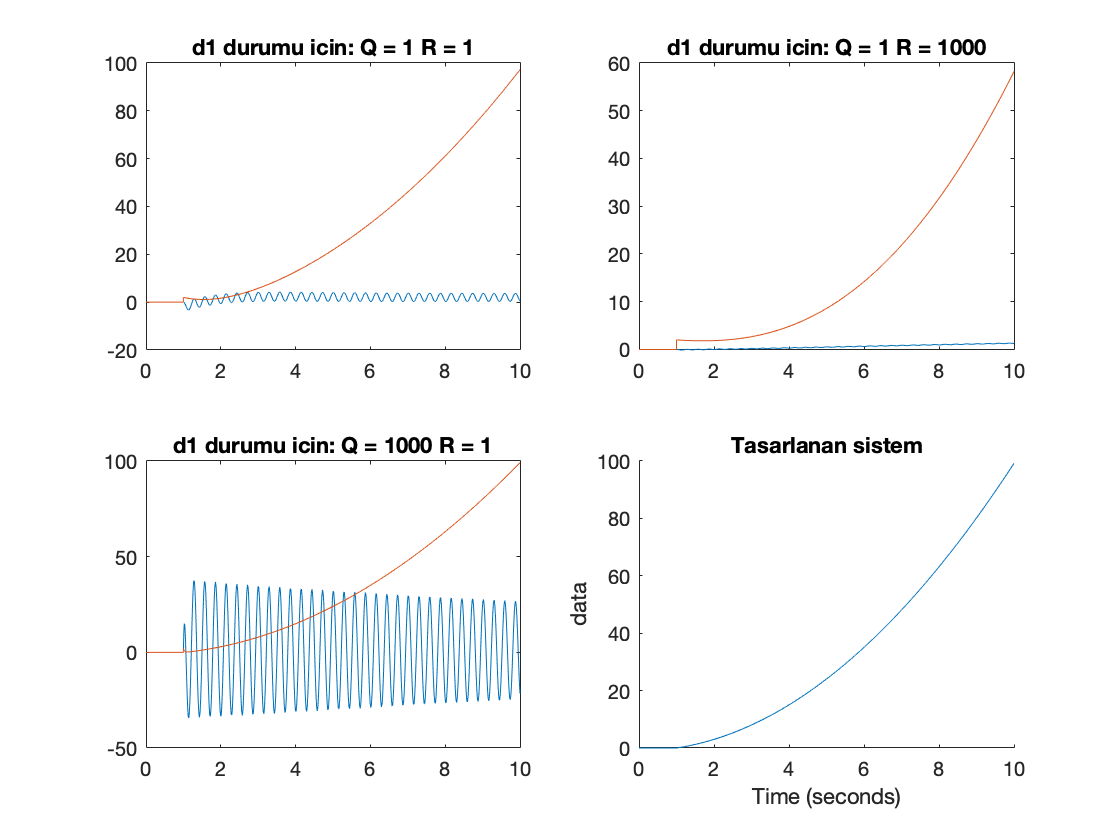

figure(2)

subplot(2,2,1)
plot(kal1)%d1 durum Q=1 R=1 icin cizdir
hold on
plot(sist_out1')%kalman filtresli sistem cikisi Q=1 R=1 icin cizdir
hold off
title('d1 durumu icin: Q = 1 R = 1')

subplot(2,2,2)
plot(kal2)%d1 durum Q=1 R=1000 icin cizdir
hold on
plot(sist_out2)%kalman filtresli sistem cikisi Q=1 R=1000 icin cizdir
hold off
title('d1 durumu icin: Q = 1 R = 1000')

subplot(2,2,3)
plot(kal3)%kalman filtresli sistem cikisi Q=1000 R=1 icin cizdir
hold on
plot(sist_out3)%kalman filtresli sistem cikisi Q=1000 R=1 icin cizdir
hold off
title('d1 durumu icin: Q = 1000 R = 1')

subplot(2,2,4)
hold on
plot(sistem_out)%kalman filtresi olmayan sistem cikisi cizdir
title('Tasarlanan sistem')
hold off

x1 icin Kalman Filtresi uygulanmış toWorkspaceler Scripte cekilir

%kalman filtresi x1 durum ciktilari
kal1x = model.kal1x;
kal2x = model.kal2x;
kal3x = model.kal3x;

sist_out1 = model.out1;
sist_out2 = model.out2;
sist_out3 = model.out3;

sistem_out = model.sistem_out; %filtresiz sistem ciktisi

Sonrasinda kalman filtreli ciktilar cizdirilir

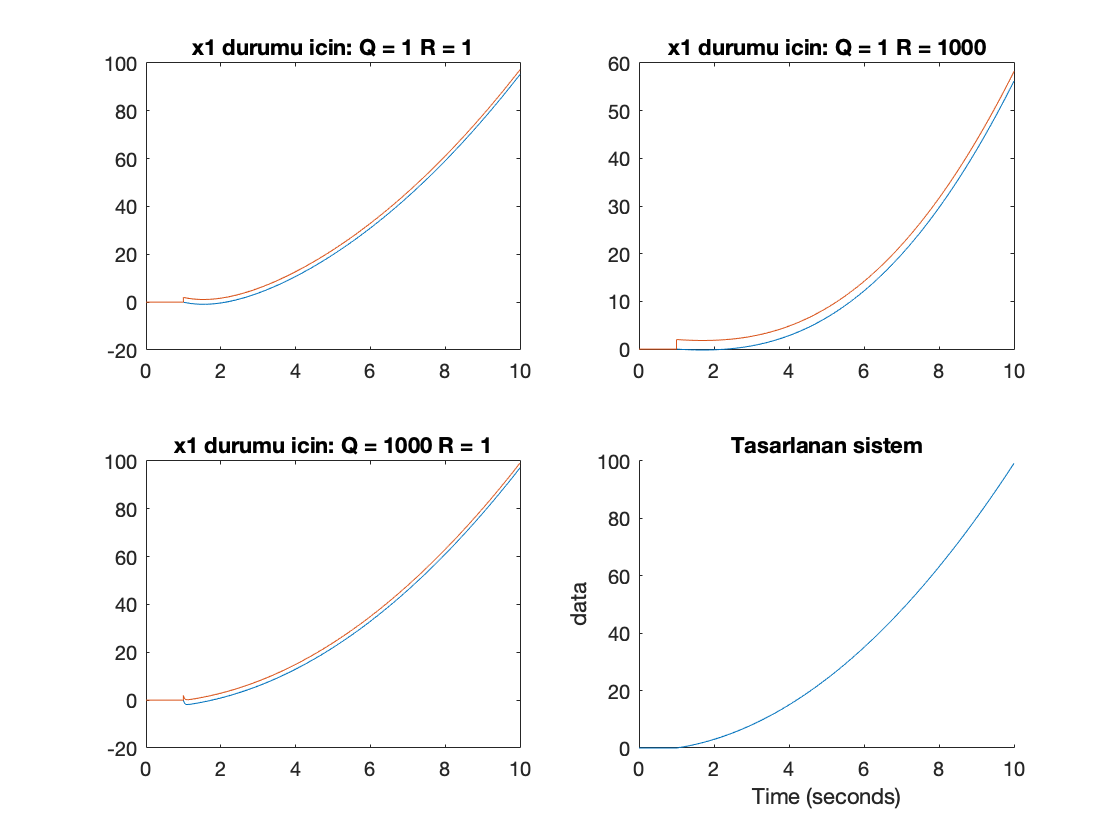

figure(3)

subplot(2,2,1)
plot(kal1x)%x1 durum Q=1 R=1 icin cizdir
hold on
plot(sist_out1')%kalman filtresli sistem cikisi Q=1 R=1 icin cizdir
hold off
title('x1 durumu icin: Q = 1 R = 1')

subplot(2,2,2)
plot(kal2x)%x1 durum Q=1 R=1000 icin cizdir
hold on
plot(sist_out2)%kalman filtresli sistem cikisi Q=1 R=1000 icin cizdir
hold off
title('x1 durumu icin: Q = 1 R = 1000')

subplot(2,2,3)
plot(kal3x)%x1 Q=1000 R=1 icin cizdir
hold on
plot(sist_out3)%kalman filtresli sistem cikisi Q=1000 R=1 icin cizdir
hold off
title('x1 durumu icin: Q = 1000 R = 1')

subplot(2,2,4)
hold on
plot(sistem_out)%kalman filtresi olmayan sistem cikisi cizdir
title('Tasarlanan sistem')
hold off

a1 icin Kalman Filtresi uygulanmış toWorkspaceler Scripte cekilir

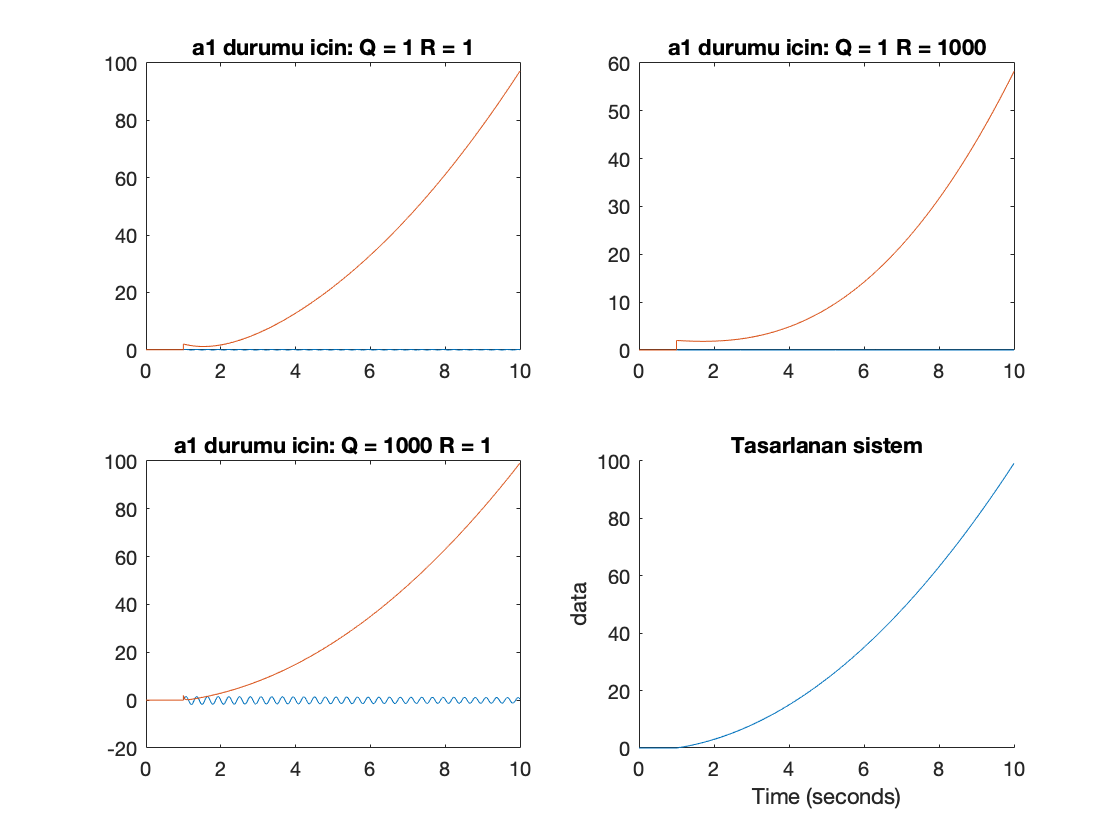

kal1a = model.kal1a;
kal2a = model.kal2a;
kal3a = model.kal3a;

sist_out1 = model.out1;
sist_out2 = model.out2;
sist_out3 = model.out3;

sistem_out = model.sistem_out;

figure(4)

subplot(2,2,1)
plot(kal1a)%a1 durum Q=1 R=1 icin cizdir
hold on
plot(sist_out1')%kalman filtresli sistem cikisi Q=1 R=1 icin cizdir
hold off
title('a1 durumu icin: Q = 1 R = 1')

subplot(2,2,2)
plot(kal2a)%a1 durum Q=1 R=1000 icin cizdir
hold on
plot(sist_out2)%kalman filtresli sistem cikisi Q=1 R=1000 icin cizdir
hold off
title('a1 durumu icin: Q = 1 R = 1000')

subplot(2,2,3)
plot(kal3a)%kalman filtresli sistem cikisi Q=1000 R=1 icin cizdir
hold on
plot(sist_out3)%kalman filtresli sistem cikisi Q=1000 R=1 icin cizdir
hold off
title('a1 durumu icin: Q = 1000 R = 1')

subplot(2,2,4)
hold on
plot(sistem_out)%kalman filtresi olmayan sistem cikisi cizdir
title('Tasarlanan sistem')
hold off

v1 icin Kalman Filtresi uygulanmış toWorkspaceler Scripte cekilir

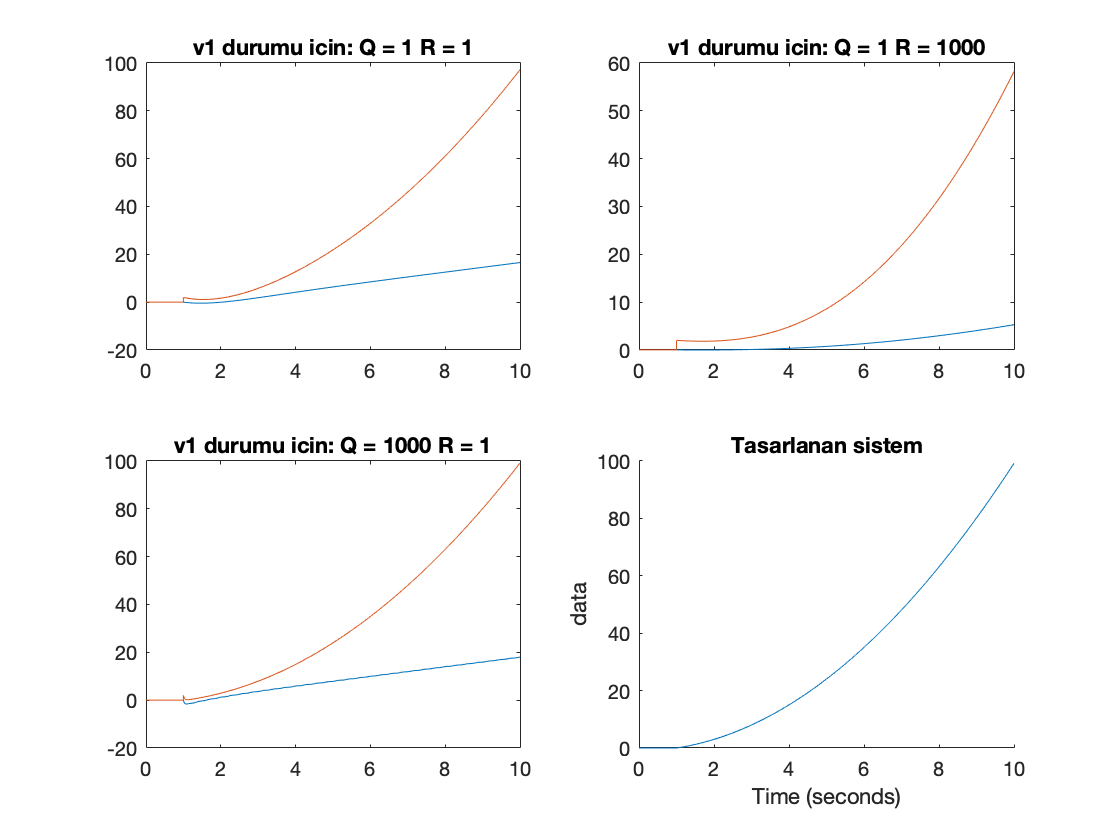

kal1v = model.kal1v;
kal2v = model.kal2v;
kal3v = model.kal3v;

sist_out1 = model.out1;
sist_out2 = model.out2;
sist_out3 = model.out3;

sistem_out = model.sistem_out;

figure(5)

subplot(2,2,1)
plot(kal1v)%v1 durum Q=1 R=1 icin cizdir
hold on
plot(sist_out1')%kalman filtresli sistem cikisi Q=1 R=1 icin cizdir
hold off
title('v1 durumu icin: Q = 1 R = 1')

subplot(2,2,2)
plot(kal2v)%v1 durum Q=1 R=1000 icin cizdir
hold on
plot(sist_out2)%kalman filtresli sistem cikisi Q=1 R=1000 icin cizdir
hold off
title('v1 durumu icin: Q = 1 R = 1000')

subplot(2,2,3)
plot(kal3v)%kalman filtresli sistem cikisi Q=1000 R=1 icin cizdir
hold on
plot(sist_out3)%kalman filtresli sistem cikisi Q=1000 R=1 icin cizdir
hold off
title('v1 durumu icin: Q = 1000 R = 1')

subplot(2,2,4)
hold on
plot(sistem_out)%kalman filtresi olmayan sistem cikisi cizdir
title('Tasarlanan sistem')
hold off

# **BOLUM 3**

**Regulation Sistemi Tasarimi = Kontrolcu**

Basta bu devre icin tasarlanilmak istenen kontrolcunun kaba taslak hali:

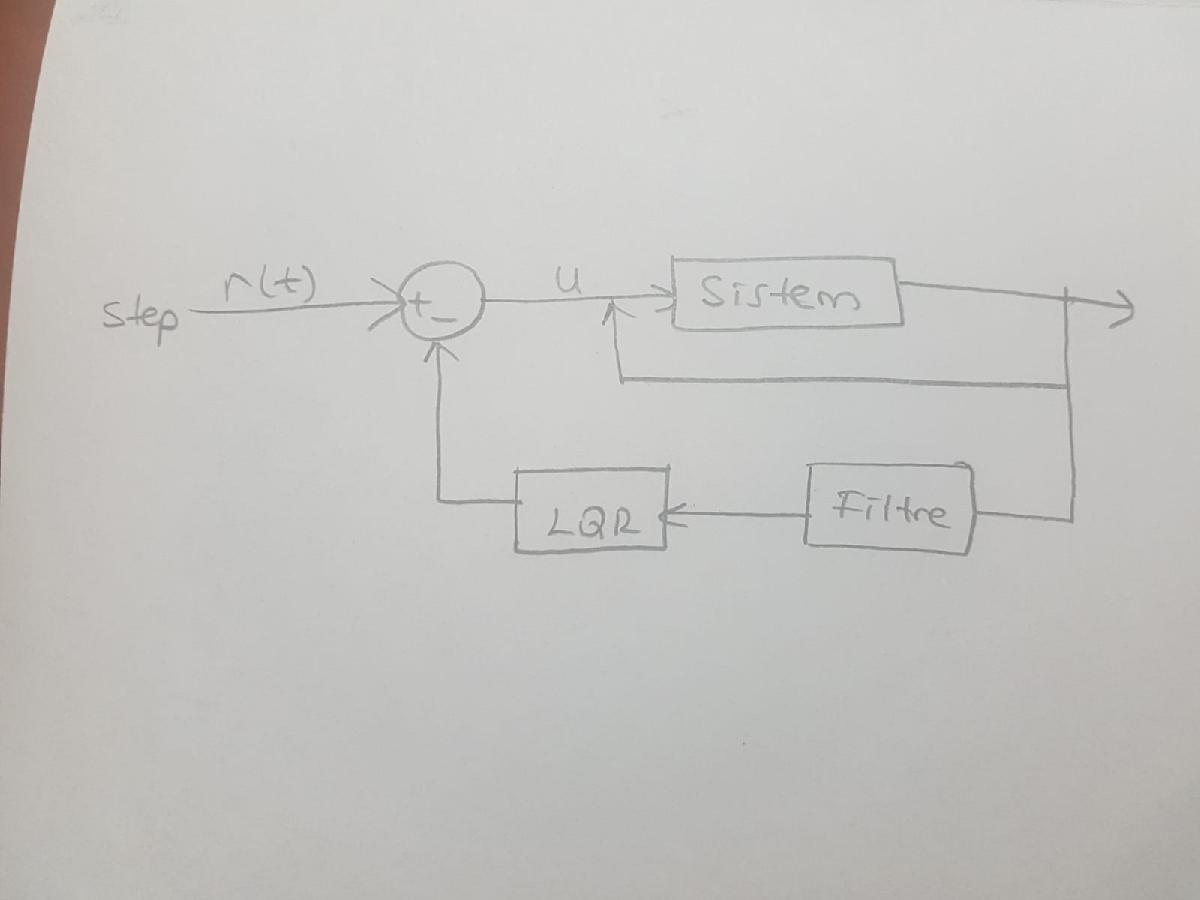

Q = 1 * eye(4); %4x4'luk bir birim matris olsun
R = 1; 
K = lqr(sistem,Q,R);

Olusturulan sistem matrisleri cekilir

Am = sistem.A;
Bm = sistem.B;
Cm = sistem.C;
Dm = sistem.D;

**% Regulation With Close Loop System**

To make our system short we made our system like A = Am - Bm * K , B=0 , C = Am - Bm * K , D=0 Otherwise it take a lot of time

**Matlabda Regulasyon Sonrasi Sistemin Cizimi**

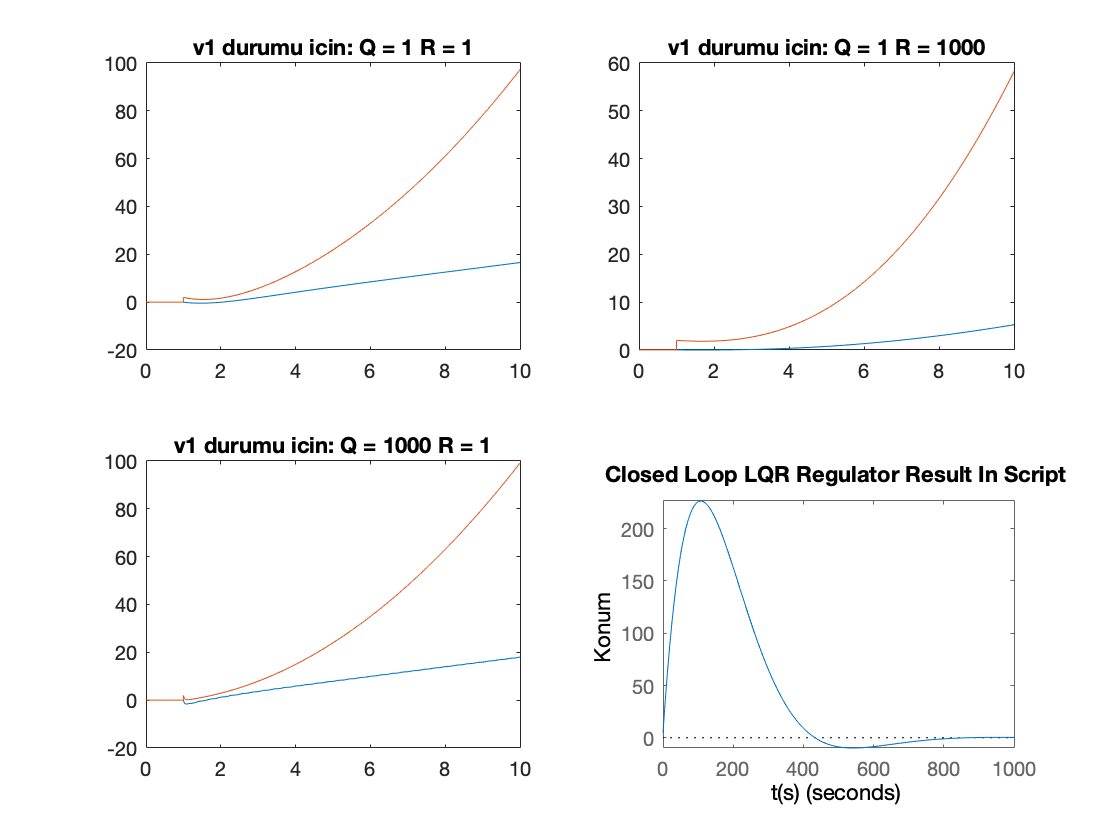

G = ss(Am - Bm * K , zeros(size(Bm)) , Cm - Dm * K , zeros(size(Dm)));

initial(G,[5 5 5 5])
ylabel('Konum');
xlabel('t(s)');
title('Closed Loop LQR Regulator Result In Script');

**Simulinkte Cizim**

model = sim('REGULATORSYSTEM')

Simulation aborted

t = model.tout;

figure(6)
regulatorsistemout = model.sist_out;
plot(regulatorsistemout)
title('Closed Loop LQR Regulator Result In Simulink')

regx1out1 = model.regx1out1;
regv1out1 = model.regv1out1;
rega1out1 = model.rega1out1;
regd1out1 = model.regd1out1;
regout = model.regout;

nonx1out = model.nonx1out;
nonv1out = model.nonv1out;
nona1out = model.nona1out;
nond1out = model.nond1out;
nlout = model.nlout;

**Regulasyon Yapilmis Sistemlerin Grafik Cizimleri**

figure(7)

subplot(2,2,1)
plot(regx1out1)%v1 durum Q=1 R=1 icin cizdir
hold on
plot(regout)%regrsyonlu sistem ciktisi
title('regrsyonlu x1 durumu (Q = 1 R = 1) ve nonlinear sistem ciktisi')
hold off

subplot(2,2,2)
plot(regv1out1)%v1 durum Q=1 R=1 icin cizdir
hold on
plot(regout)%regrsyonlu sistem ciktisi
title('regrsyonlu v1 durumu (Q = 1 R = 1) ve nonlinear sistem ciktisi')
hold off

subplot(2,2,3)
plot(rega1out1)%a1 durumu icin Q=1 R=1 icin cizdir
hold on
plot(regout)%regrsyonlu sistem ciktisi
title('regrsyonlu a1 durumu (Q = 1 R = 1) ve nonlinear sistem ciktisi')
hold off

subplot(2,2,4)
plot(regd1out1)%d1 durumu icin Q=1 R=1 icin cizdir
hold on
plot(regout)%nonlinear sistem ciktisi
title('regrsyonlu d1 durumu (Q = 1 R = 1) ve sistem ciktisi');
hold off

**Nonlineer sistemlerin graffik cizimleri**

figure(8)

subplot(2,2,1)
plot(nonx1out)%v1 durum Q=1 R=1 icin cizdir
hold on
plot(nlout)%nonlinear sistem ciktisi
title('nonlinear x1 durumu (Q = 1 R = 1) ve nonlinear sistem ciktisi')
hold off

subplot(2,2,2)
plot(nonv1out)%v1 durum Q=1 R=1 icin cizdir
hold on
plot(nlout)%nonlinear sistem ciktisi
title('nonlinear v1 durumu (Q = 1 R = 1) ve nonlinear sistem ciktisi')
hold off

subplot(2,2,3)
plot(nona1out)%a1 durumu icin Q=1 R=1 icin cizdir
hold on
plot(nlout)%nonlinear sistem ciktisi
title('nonlinear a1 durumu (Q = 1 R = 1) ve nonlinear sistem ciktisi')
hold off

subplot(2,2,4)
plot(nond1out)%d1 durumu icin Q=1 R=1 icin cizdir
hold on
plot(nlout)%nonlinear sistem ciktisi
title('nonlinear d1 durumu (Q = 1 R = 1) ve nonlinear sistem ciktisi');
hold off

# **SONUCLAR**

Tasarlanan basit ama pek çok şekilde kullanılacak olan sistemin ve kontrolcünün doğrulukları elde edilen grafiklerle sağlanmıştır. Fakat bu işlemler yapılırken bilinmeyenlerin varsayımları üzerinde hesaplamalar yapılmıştır. Bu değerler gerçekte değişebilir. Bunun yanı sıra devrelere de verilen step kavramı, yanıtın başlangıçta sıfırdan başlayıp daha sonra bir maksimum değere yükseleceği ve daha sonra sürenin geri kalanı boyunca aynı kalacağını ifade eder. Tasarlanan sistemlerin grafik çıktılarında da gösterilen yanıtın başlangıç değeri sıfırdır. Eğrinin doğası gereği sistem hasar görebilir. Bunun düzenlemek için kontrolcü tasarlandı ve böylece sistem çıktısı biraz daha hatalardan temizlendi.

# **PROJE TAMAMLANINCA YAPILACAKLAR**

Projenin sonucunda fabrikalara kurulacak geri dönüşümler tesislerinden elde edilen malzeme taşınması kolaylaştırılmıştır ve böylece fabrikalar için ekstra maliyet yükü ortadan kaldırılmıştır. Problemdeki ana sorun geri dönüşüm fabrikalarının kısa vadede hızlı hasar görmesi ve bunun maliyeti dolayısıyla Türkiye’de pek çok büyük üretim hattına sahip olan fabrikanın geri dönüşüm tesisi kurmamasıydı. Kurulan ve tasarlanan sistem sayesinde fabrikaları kolaylık sağlanabilir ve çok ciddi ölçüde hem firmalar tasarruf yapabilir hem de geri dönüşümün ülke ekonomisine yaygınlaştırılması dolayısıyla faydası dokunabilir.